# Datos recibidos

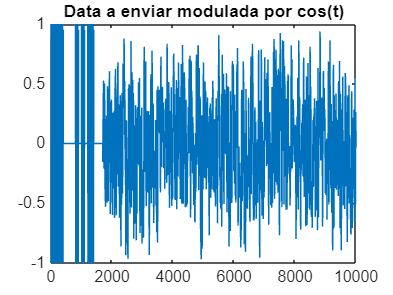


read2 = read_float_binary('SENT.bin')';

figure
plot(read2(1:10000))
title("Data a enviar modulada por cos(t)")

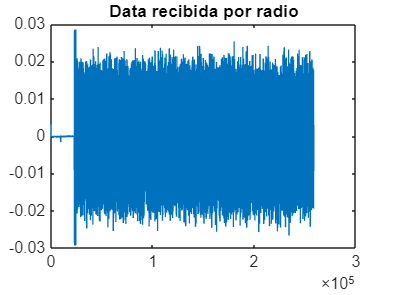

rec = read_float_binary('TEST_OOK_NOGAIN.bin')';

figure
plot(rec)
title("Data recibida por radio")

%get to preamble start

% newrec = rec(23094:end); %manual sync,
% figure
% plot(newrec(1:10000))
% title("Data recibida, inicio (preamb+data)")


% Suppose you have:
%   modulatedSignal = <16-bit preamble, each bit upsampled 100 times, length 1600>
%   rxSignal        = <your captured signal from hardware, presumably >1600 samples>

rxSignal = rec;

% Call the function
[startIdx, corrVal, lags] = findPreambleStart(rxSignal, modulatedSignal);

% Now 'startIdx' should be the sample index in 'rxSignal' 
% where the preamble aligns best with 'modulatedSignal'.
fprintf('Estimated preamble start index = %d\n', startIdx);

Estimated preamble start index = 23092


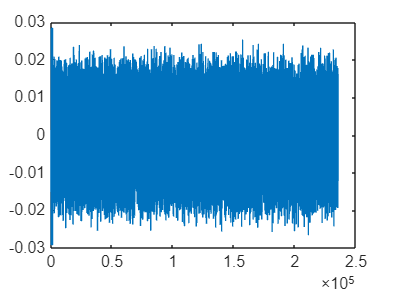


% If your actual BPSK data starts right after the preamble, 
% the data start would be:
dataStartIdx = startIdx + length(modulatedSignal);

% You can then extract your BPSK data samples from rxSignal like:
bpskData = rxSignal(dataStartIdx : end);

plot(rxSignal(startIdx:end))

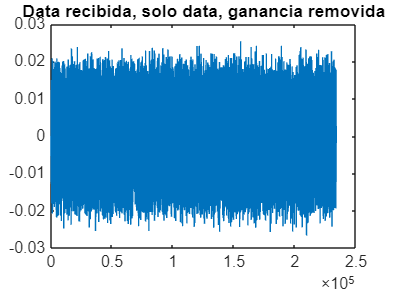

%remove preamble
newrec_packet = newrec(1+length(preamble)*100:end);

%normalizar respecto a señal recibida

%newrec_packet = newrec_packet/max(newrec_packet);

%normalizar respecto a canal H (remover gain)

newrec_packet = newrec_packet;%*MAX_H;

figure
plot(newrec_packet)
title("Data recibida, solo data, ganancia removida")

% og_pack = read2(1+length(pream)*100:end)*MAX_H;
% figure
% plot(og_pack)
% title("Data original con H incluido, sin ganancia")


% noH_mod_pack = read7(1+length(pream)*100:end);
% figure
% plot(noH_mod_pack)
% title("Data original sin H incluido")


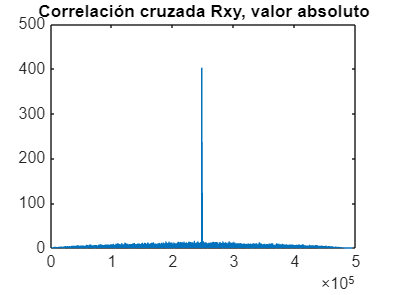


%y = x conv h
%Ryx = Rxx conv h

Rxy = xcorr(newrec_packet,txFiltered');

figure
plot(abs(Rxy))
title("Correlación cruzada Rxy, valor absoluto")

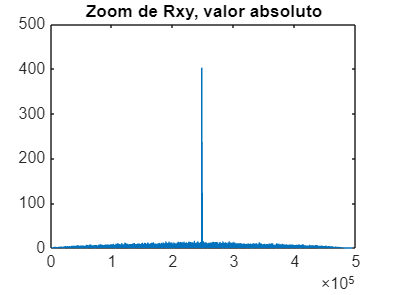


figure
plot(abs(Rxy))

title("Zoom de Rxy, valor absoluto")

%% Parameters
numSymbols      = length(txBits);          % Number of BPSK symbols
samplesPerSym   = samplesPerSym;             % Oversampling factor (example)
rcosFilt        = rcFilter;
                  % Example sqrt raised cosine design
h_est           = newresponse;     % Example of estimated channel [adapt or replace with your own]
                                  % If you have an L-tap channel, h_est should be length L.

% rxSignal
rxChannelOut = newrec_packet';

%% 4) Receiver: Matched Filtering
% First, refilter with rcosFilt
rxMatchedFull = filter(rcosFilt, 1, rxChannelOut);

% Compensate the filter delay
rxMatchedFull = rxMatchedFull(filtDelay+1 : end-filtDelay);

%% 5) Frequency-Domain Zero-Forcing
%
% We’ll do the FFT-based zero-forcing on rxMatchedFull.
% The length of rxMatchedFull is typically numSymbols*samplesPerSym
% minus some samples due to filter conv. Let’s call that length L.
L = length(rxMatchedFull);

% We want to avoid circular convolution issues:
Nfft = 2^nextpow2(L + length(h_est) - 1);  % a safe FFT size

% Zero-pad the received signal
rxPadded = [rxMatchedFull; zeros(Nfft - L, 1)];

% Zero-pad the channel as well
hPadded  = [h_est(:); zeros(Nfft - length(h_est), 1)];

% Go to frequency domain
RX_F = fft(rxPadded, Nfft);
H_F  = fft(hPadded, Nfft);

% Zero-forcing in frequency domain
epsilon = 1e-10;
ZF_F = RX_F .* (1./(H_F + epsilon)); 

% IFFT to get time-domain equalized signal
zfTime = ifft(ZF_F, Nfft);

% Now, zfTime has length Nfft. We only care about the first L samples
% (which correspond to the original, non-padded region).
zfTime = zfTime(1:L);

%% 6) Downsample and Symbol Decisions
% We originally had an upsample factor of 8. Let’s downsample:
rxDownsampled = downsample(zfTime, samplesPerSym);

% BPSK detection
demodBits = real(rxDownsampled) > 0;

%% 7) Calculate BER
% We might have lost some symbols at the edges due to convolution.
% Let’s figure out how many valid symbols remain. 
% If we designed everything carefully, we should still have around `numSymbols`:
validSymCount = length(demodBits);  
minLen = min(validSymCount, length(txBits));

% Compare only the overlapping region
demodBitsTrim = demodBits(1:minLen);
txBitsTrim    = txBits(1:minLen);

numErrors = sum(demodBitsTrim ~= txBitsTrim);
BER       = numErrors / minLen;

fprintf('\nFrequency-Domain Zero-Forcing Results:\n');


Frequency-Domain Zero-Forcing Results:


fprintf('  Number of Errors = %d (out of %d symbols)\n', numErrors, minLen);

  Number of Errors = 7158 (out of 23371 symbols)


fprintf('  BER = %g\n', BER);

  BER = 0.306277


%demod = newrec_packet./ cos(2 * pi * 100e3 * [1:length(newrec_packet)]);

% Filtro pasa bajos
% fc = 5000;  % Frecuencia de corte del filtro (ajusta si es necesario)
% [b, a] = butter(6, 0.01);  % Filtro Butterworth de orden 6
% yf = filter(b, a, newrec_packet);  
% xf = filter(b, a, noH_mod_pack); 


% Filtrado paso bajo para extraer la señal en banda base
fs = 2e6;                % Frecuencia de muestreo en Hz
fc = 100e3;              % Frecuencia de la portadora en Hz

filtro_pb = designfilt('lowpassiir', 'FilterOrder', 8, ...
                       'PassbandFrequency', 0.5 * fc, ...
                       'PassbandRipple', 0.5, ...
                       'SampleRate', fs);


% rxbits = demodulate_signal(rx_bb_signal(1+length(pream)*100:2445300), 100);
% 
% 
% data_bits2 = data_bits;
% data_bits2(data_bits2==-1)=-0;
% 
% ber = calculate_ber(rxbits, data_bits2(1:length(rxbits)))

% filtercorr = filtfilt(filtro_pb, abs(Rxy));
% plot(filtercorr)
% title("Correlación cruzada Rxy, valor absoluto")


function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

function bits = demodulate_signal(signal, samples_per_bit)
    % Inicializar vector de bits
    num_bits = length(signal) / samples_per_bit;
    bits = zeros(1, num_bits);

    % Determinar el valor de cada bit
    for i = 1:num_bits
        segment = signal((i-1)*samples_per_bit + 1 : i*samples_per_bit);
        if mean(segment) > 0
            bits(i) = 1;
        else
            bits(i) = 0;
        end
    end
end


function ber = calculate_ber(bits_received, bits_original)
    % Verificar que los arreglos tengan la misma longitud
    if length(bits_received) ~= length(bits_original)
        error('Los arreglos de bits deben tener la misma longitud');
    end
    
    % Calcular el número de errores
    num_errors = sum(bits_received ~= bits_original);
    
    % Calcular el BER
    ber = num_errors / length(bits_original);
end


function [startIndex, corrVec, lagVec] = findPreambleStart(rxSignal, preambleSignal)
% FINDPREAMBLESTART Finds where a known preamble begins in a received signal
%   [startIndex, corrVec, lagVec] = findPreambleStart(rxSignal, preambleSignal)
%
% INPUTS:
%   rxSignal       : The full received signal (row or column vector).
%   preambleSignal : The known preamble samples (row or column vector).
%
% OUTPUTS:
%   startIndex : The estimated index in rxSignal where the preamble starts.
%   corrVec    : The cross-correlation array (for optional debugging/plotting).
%   lagVec     : The corresponding lags vector from xcorr.

    % Ensure column vectors for consistency
    rxSignal       = rxSignal(:);
    preambleSignal = preambleSignal(:);

    % 1) Cross-correlation
    [corrVec, lagVec] = xcorr(rxSignal, preambleSignal);

    % 2) Find the lag where correlation magnitude is maximum
    [~, idxMax] = max(abs(corrVec));

    bestLag = lagVec(idxMax);

    % 3) Convert that lag to a start index in rxSignal
    %
    %   If bestLag >= 0:
    %       preamble starts at sample (bestLag + 1)
    %   If bestLag < 0, the best alignment is "before" rxSignal's first sample, 
    %   so effectively the start is near index 1. We'll clamp it to avoid negative indexing.
    %
    startIndex = bestLag + 1;  % +1 because MATLAB is 1-based indexing

    if startIndex < 1
        startIndex = 1;
    end

    % Optionally, you can check if the entire preamble fits in rxSignal:
    if startIndex + length(preambleSignal) - 1 > length(rxSignal)
        warning('Preamble extends beyond the length of rxSignal. Check capture length.');
    end
end
